# Team Work 1

# Train a DDPG Agent for the Warehouse Robot

**Angélica Alemán Cabrales**

**Vladimir Frunza **

## Clear settings

commandS to clear the command window and the workspace variables.

clc, clear

## Define the environment

Discrete states and actions. Six continuous numeric state variables. Two continuous actions in the range [-1 1].

obsInfo = rlNumericSpec([6 1]);
actInfo = rlNumericSpec([2 1],"UpperLimit",1,"LowerLimit",-1);

env = rlSimulinkEnv("whrobot","whrobot/controller",obsInfo,actInfo);
env.ResetFcn = @randomstart;

## Define the trained agent

dt = 0.25;

opts = rlDDPGAgentOptions("SampleTime",dt,"ExperienceBufferLength",1e6,"MiniBatchSize",128);
agent = rlDDPGAgent(obsInfo,actInfo,opts);

learnopts = rlOptimizerOptions("LearnRate",5e-5,"GradientThreshold",10);
agent.AgentOptions.ActorOptimizerOptions = learnopts;
agent.AgentOptions.CriticOptimizerOptions = learnopts;

## Train the agent

Check to train agent from scratch.

dotraining = false;
load_predefined_agents = false;
maxsteps = round(30/dt);  % max episode time of 30s (simulation time)
clear plotRobot           % make sure visualization starts fresh   

Train agent or load pretrained agent from file. The pretrained agent `trainedNN` was trained for *NN*$\times 10^3$ episodes.

if dotraining
    opts = rlTrainingOptions( ...
        "MaxStepsPerEpisode",maxsteps, ... 
        "MaxEpisodes",15000, ...
        "ScoreAveragingWindowLength",50, ...
        "StopTrainingCriteria","AverageReward", ...
        "StopTrainingValue", 200);
    info = train(agent,env,opts);
    agent_basereward15 = agent
    matfile("TrainedAgent.mat")
    save("TrainedAgent.mat", "agent_basereward15", "-append")
else 
    if load_predefined_agents
        load trainedDDPG
        agent = trained05;
    else
        load TrainedAgent
        agent = agent_newreward15;
    end
end

## Evaluate the agent

Run multiple simulations.

numsim = 20;
simout = sim(agent,env,rlSimulationOptions("MaxSteps",maxsteps,"NumSimulations",numsim))

simout = 20×1 struct array with fields:
    Observation
    Action
    Reward
    IsDone
    SimulationInfo


Episodes can end because (1) the robot succeeded, (2) the robot crashed into the shelves, (3) the episode reached the `MaxSteps` limit.

Determine which episodes were terminated (vs ran to `MaxSteps` limit). Then determine which of those were successful terminations (positive reward).

completed = arrayfun(@(x) any(x.IsDone.Data==1),simout);
succeeded = arrayfun(@(x) x.Reward.Data(x.IsDone.Data==1)>0,simout(completed));

Get the counts from each group.

Nsuccess = nnz(succeeded);
Ncrash = nnz(completed) - Nsuccess;
Nnoresult = numsim - nnz(completed);

% Print results for trained agent
fprintf("Trained Agent Results:\n");

Trained Agent Results:


fprintf("Successful Runs: %d\n", Nsuccess);

Successful Runs: 0


fprintf("Crashed Runs: %d\n", Ncrash);

Crashed Runs: 0


fprintf("Runs Didn't Reach Goal: %d\n", Nnoresult);

Runs Didn't Reach Goal: 20


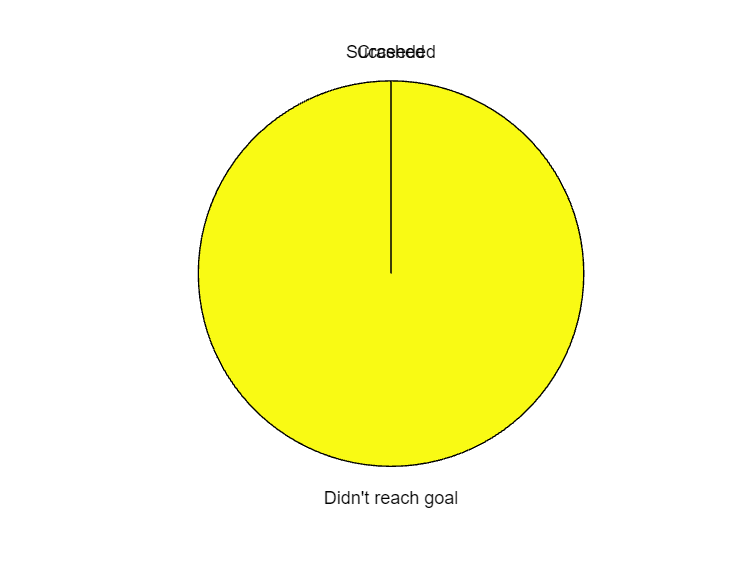


pie([Nsuccess;Ncrash;Nnoresult],[],["Succeeded","Crashed","Didn't reach goal"])

Get the time taken for successful runs.

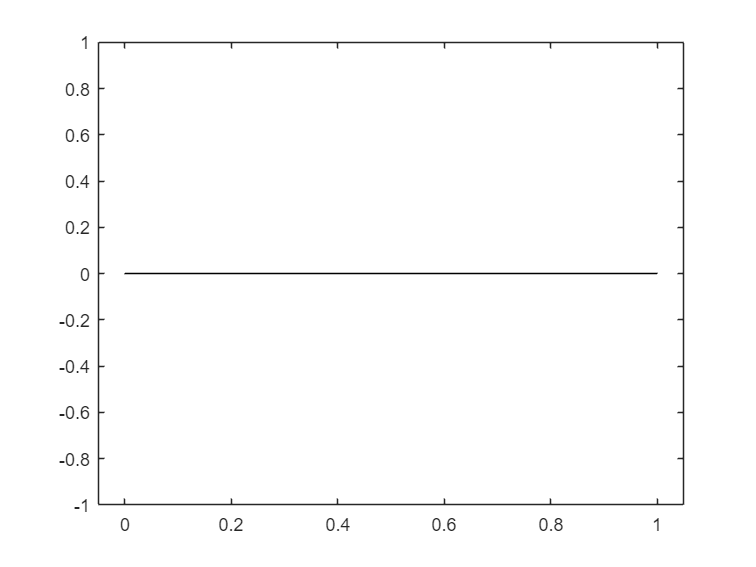

T = arrayfun(@(x) x.IsDone.Time(end),simout(succeeded));
histogram(T)

mean(T)

ans = NaN

## Define the non-trained agent (new)

% Create a new agent for the non-trained scenario
nonTrainedAgent = rlDDPGAgent(obsInfo,actInfo,opts);

## Evaluate the non-trained agent (new)

Run the same number of simulations as defined before.

% Run simulations with the non-trained agent
simoutNonTrained = sim(nonTrainedAgent, env, rlSimulationOptions("MaxSteps", maxsteps, "NumSimulations", numsim));

% Similar evaluation process for non-trained agent
completedNonTrained = arrayfun(@(x) any(x.IsDone.Data==1),simoutNonTrained);
succeededNonTrained = arrayfun(@(x) x.Reward.Data(x.IsDone.Data==1)>0,simoutNonTrained(completedNonTrained));

NsuccessNonTrained = nnz(succeededNonTrained);
NcrashNonTrained = nnz(completedNonTrained) - NsuccessNonTrained;
NnoresultNonTrained = numsim - nnz(completedNonTrained);

## Results for the non-trained agent (new)

Display results for non-tained agent

% Print results for non-trained agent
fprintf("Non-Trained Agent Results:\n");

Non-Trained Agent Results:


fprintf("Successful Runs: %d\n", NsuccessNonTrained);

Successful Runs: 0


fprintf("Crashed Runs: %d\n", NcrashNonTrained);

Crashed Runs: 14


fprintf("Runs Didn't Reach Goal: %d\n", NnoresultNonTrained);

Runs Didn't Reach Goal: 6


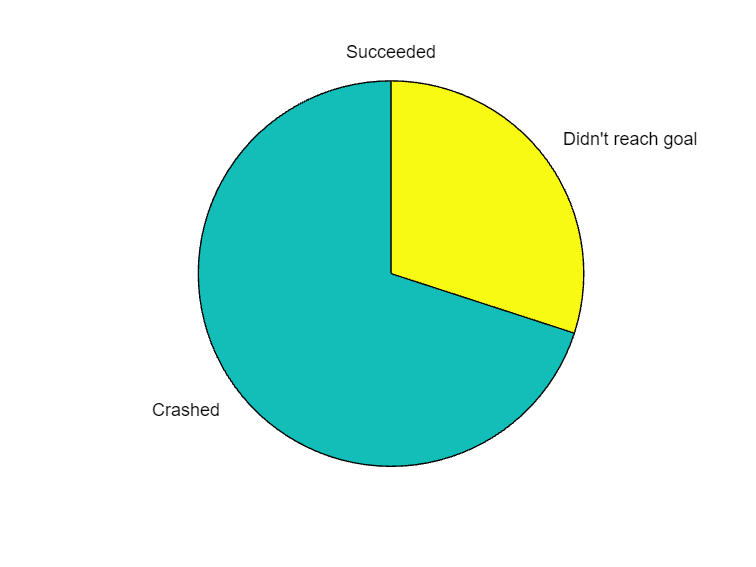


% Visualize results for non-trained agentclc,
pie([NsuccessNonTrained; NcrashNonTrained; NnoresultNonTrained], [], ["Succeeded", "Crashed", "Didn't reach goal"]);


TNonTrained = arrayfun(@(x) x.IsDone.Time(end),simoutNonTrained(succeededNonTrained));
figure;
histogram(TNonTrained);

mean(TNonTrained);